% load the running definition files exported from Peter's analysis pipeline
filepath2 = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/RunningRestingDefs/RunningDef_AChMut/'

filepath2 = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/RunningRestingDefs/RunningDef_AChMut/'

cd(filepath2)

Running_def_files = dir(filepath2)

Running_def_files = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Running_def_files(1:2) = [];

DataParameter_file = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/AChMut/DataParameters_AChMut.csv'

DataParameter_file = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/AChMut/DataParameters_AChMut.csv'

DataParameters = readtable(DataParameter_file,  'NumHeaderLines', 0)

DataParameters = 4×5 table
    MouseID    LaserPower                  Basename                                                                    Path                                                                   Experiment             
    _______    __________    ____________________________________    ________________________________________________________________________________________________________    ____________________________________

      112          1         {'20220208_112_8_AChMut_RvR_001'   }    {'/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/AChMut/20220208_112_8_AChMut_RvR_001'   }    {'20220208_112_8_AChMut_RvR_001'   }
      123          1         {'20220714_PM28_123_AChmut_RvR_001'}    {'/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/AChMut/20220714_PM28_123_ACh

DataParameters_Basename = {};
for i = 1:size(DataParameters,1)

    DataParameters_Basename{i} = cell2mat(DataParameters.Basename(i));
end

Running_durations_all = {};
Running_index_all = {};
Running_speed_median_all = {};
Speed_all = {};
Time_all = {};
RunningDef_all = {};
basename_all = {};

for i = 1:length(Running_def_files)
    Running_duration = [];
    RunningDef_individual_file = Running_def_files(i).name;

    RunningDef_all_info = readtable(RunningDef_individual_file, 'NumHeaderLines', 1);
    RunningDef = table2array(RunningDef_all_info(:,4));
    RunningDef_all{i} = RunningDef;
    Speed = table2array(RunningDef_all_info(:,2));
    Speed_all{i} = Speed;
    Time_individual = table2array(RunningDef_all_info(:,1));
    Time_all{i} = Time_individual;

    Running_indexs = {};
    Running_speed_median = [];
    Running_index = [];
    Running_durations = [];
    Running_duration = 0;
    k = 1;

    for j = 1:length(RunningDef)

        if RunningDef(j) == 1
            Running_duration = Running_duration + 1;
            Running_index = [Running_index j];
        end

        if RunningDef(j) == 0
            if Running_duration > 0
                Running_indexs{k} = Running_index;
                k = k+1;
                Running_speed_median = [Running_speed_median median(abs(Speed(Running_index)))];
                Running_index = [];
                Running_durations = [Running_durations Running_duration];
                Running_duration = 0;
            end
        end
    end

    Running_durations_all{i} = Running_durations;
    Running_index_all{i} = Running_indexs;
    Running_speed_median_all{i} = Running_speed_median;

%     eval(['Running_indexs_', animals{i}, '_', lasers{i}, ' = Running_indexs;'])
%     eval(['Running_speed_median_', animals{i}, '_', lasers{i}, ' = Running_speed_median;'])
%     eval(['Running_durations_', animals{i}, '_', lasers{i}, ' = Running_durations;'])
%     

    
end

data_summary_csv = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/AChMut/Scatter Plot (Raw)_grouped_AChMut_Revision_20230725.csv';
RvR_data_summary = readtable(data_summary_csv, 'NumHeaderLines', 1)

RvR_data_summary = 117×7 table
                  Var1                   Var2    Var3    Var4       Var5        Var6      Var7 
    _________________________________    ____    ____    ____    __________    ______    ______

    {'20220208_112_8_AChMut_RvR_001'}    112      1       0      4.3671e+05    2.5103    4.1735
    {'20220208_112_8_AChMut_RvR_001'}    112      1       0      4.3844e+05    2.5106    4.1732
    {'20220208_112_8_AChMut_RvR_001'}    112      1       0      4.3902e+05    2.5119    4.1701
    {'20220208_112_8_AChMut_RvR_001'}    112      1       0      4.4161e+05    2.5094     4.168
    {'20220208_112_8_AChMut_RvR_001'}    112      1       0      4.4322e+05    2.5119    4.1707
    {'20220208_112_8_AChMut_RvR_001'}    112      1       


Mouse_ID = table2array(RvR_data_summary(:,2))

Mouse_ID =    112
   112
   112
   112
   112
   112
   112
   112
   112
   112


Laser = table2array(RvR_data_summary(:,3))

Laser =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Speed = table2array(RvR_data_summary(:,4))

Speed =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


intensity = table2array(RvR_data_summary(:,5))/100000;
lft = table2array(RvR_data_summary(:,7))

lft =     4.1735
    4.1732
    4.1701
    4.1680
    4.1707
    4.1698
    4.1723
    4.1699
    4.1700
    4.1697


Mouse_ID_categorical = categorical(Mouse_ID)

Mouse_ID_categorical = 117×1 categorical array
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 
     112 


Laser_categorical = categorical(Laser);
States =  zeros(length(Speed),1);
Running_index = [];

for i = 1:length(Speed)
    if Speed(i,1) > 0
        States(i) = 1;
        Running_index = [Running_index i];
    end
end

States_categorical = categorical(States);

mouse_all = categories(Mouse_ID_categorical)

mouse_all = 4×1 cell array
    {'109'}
    {'111'}
    {'112'}
    {'123'}


laser_all = categories(Laser_categorical)

laser_all = 1×1 cell array
    {'1'}


States_all = categories(States_categorical)

States_all = 2×1 cell array
    {'0'}
    {'1'}


intensity_collection=[];
lft_collection=[];
mouseID_collection=[];
laser_collection=[];
states_collection=[];

for i=1:4
    mouse=mouse_all(i)
    

    lft_mouse=lft(find(Mouse_ID_categorical == mouse));
    intensity_mouse=intensity(find(Mouse_ID_categorical == mouse));
    speed_mouse=Speed(find(Mouse_ID_categorical == mouse));
    laser_mouse=Laser(find(Mouse_ID_categorical == mouse));
    states_mouse=States(find(Mouse_ID_categorical == mouse));

    eval(['lft_',convertStringsToChars(cell2mat(mouse)),'=lft_mouse;'])
    eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'=intensity_mouse;'])
    eval(['speed_',convertStringsToChars(cell2mat(mouse)),'=speed_mouse;'])
    eval(['laser_',convertStringsToChars(cell2mat(mouse)),'=laser_mouse;'])
    eval(['states_',convertStringsToChars(cell2mat(mouse)),'=states_mouse;'])

    for j=1:3

        lft_mouse_laser=lft_mouse(find(laser_mouse==j));
        intensity_mouse_laser=intensity_mouse(find(laser_mouse==j));
        speed_mouse_laser=speed_mouse(find(laser_mouse==j));
        states_mouse_laser=states_mouse(find(laser_mouse==j));
        lft_mouse_laser_running=lft_mouse_laser(find(states_mouse_laser==1));
        lft_mouse_laser_resting=lft_mouse_laser(find(states_mouse_laser==0));
        intensity_mouse_laser_running=intensity_mouse_laser(find(states_mouse_laser==1));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;j];
        states_collection=[states_collection;[1]];
        if isempty(intensity_mouse_laser_running)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_running)];
        end

        if isempty(lft_mouse_laser_running)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_running)];
        end

        intensity_mouse_laser_resting=intensity_mouse_laser(find(states_mouse_laser==0));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;[j]];
        states_collection=[states_collection;[0]];
        if isempty(intensity_mouse_laser_resting)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_resting)];
        end

        if isempty(lft_mouse_laser_resting)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_resting)];
        end

      
        

        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=lft_mouse_laser;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=intensity_mouse_laser;'])
        eval(['speed_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=speed_mouse_laser;'])
        eval(['states_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=states_mouse_laser;'])

        lft_mouse_laser_running = [lft_mouse_laser_running;NaN(100-length(lft_mouse_laser_running), 1)];
        lft_mouse_laser_resting = [lft_mouse_laser_resting;NaN(100-length(lft_mouse_laser_resting), 1)];
        intensity_mouse_laser_running = [intensity_mouse_laser_running;NaN(100-length(intensity_mouse_laser_running), 1)];
        intensity_mouse_laser_resting = [intensity_mouse_laser_resting;NaN(100-length(intensity_mouse_laser_resting), 1)];
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=lft_mouse_laser_running;'])
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=lft_mouse_laser_resting;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=intensity_mouse_laser_running;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=intensity_mouse_laser_resting;'])
    end

end

mouse = 1×1 cell array
    {'109'}


mouse = 1×1 cell array
    {'111'}


mouse = 1×1 cell array
    {'112'}


mouse = 1×1 cell array
    {'123'}


for i = 1:4
    mouse=mouse_all(i)
    mouse  = convertStringsToChars(cell2mat(mouse));
    eval(['a_intensity_', mouse, ' = [intensity_', mouse, '_1_resting intensity_', mouse, '_1_running];'])
    eval(['a_lft_', mouse, ' = [lft_', mouse, '_1_resting lft_', mouse, '_1_running];'])
end

mouse = 1×1 cell array
    {'109'}


mouse = 1×1 cell array
    {'111'}


mouse = 1×1 cell array
    {'112'}


mouse = 1×1 cell array
    {'123'}


cd('/Volumes/PcSSDA/AChMut/20220714_PM29_111_AChmut_RvR_002')
ExperimentName='20220714_PM29_111_AChmut_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='111'

mouse = '111'


FLIM_acq_files = dir('*FLIM00*.mat');
spcSaveFile = load(FLIM_acq_files(end).name);
FLP_start_time = spcSaveFile.spcSave.datainfo.zFLIP_triggerTime;
FLP_start_time = FLP_start_time(13:end);
FLP_start_time = GetSeconds(FLP_start_time);

speed_csv = ['speed/', ExperimentName,'_speed0.csv'];
[time_of_speed speed_raw]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
Speed_start_time = time_of_speed{2};
Speed_start_time = Speed_start_time(12:27);
Speed_start_time = GetSeconds(Speed_start_time);

Speed_time_shift = Speed_start_time - FLP_start_time

Speed_time_shift = 1.3521


analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

i=1;
filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)
time = time - Speed_time_shift;

i = 4;
time_of_speed_seconds = Time_all{i};
speed = Speed_all{i};

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


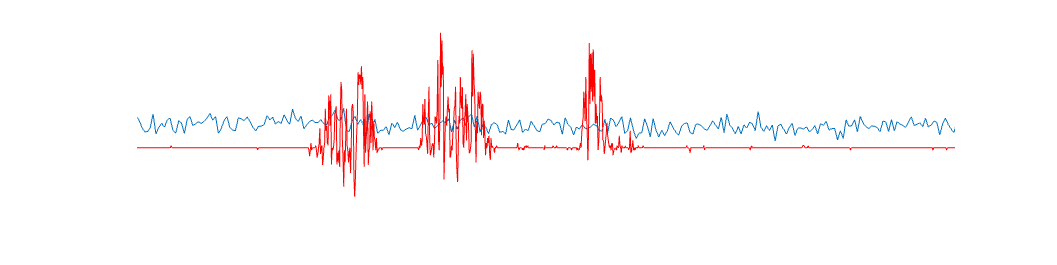

yyaxis left
plot(time,tau_empTrunc);
xlim([3200 3500])
ylim([4.15 4.3])
set(gca, 'XColor','none')
set(gca, 'YColor','none')
yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 20])
ylabel('Speed (cm/s)')
% yticks([-10 0 10 20])
xlim([3200 3500])
set(gca,'ytick',[0 20])
axis off
box off

% title('Lifetime')

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


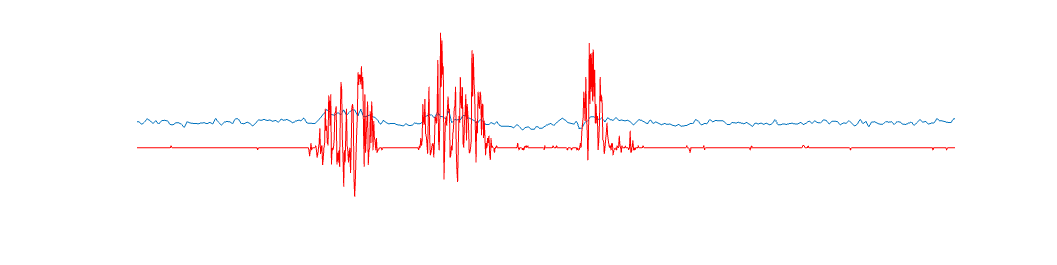

yyaxis left
plot(time,photoncount);
xlim([3200 3500])
ylim([360000 450000])
set(gca, 'XColor','none')
set(gca, 'YColor','none')
yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 20])
% yticks([-10 0 10 20])
xlim([3200 3500])
set(gca,'ytick',[0 20])
ylabel('Speed (cm/s)')
axis off
box off

% title('Intensity')

speed_max = max(speed(find(time_of_speed_seconds >= 3200 & time_of_speed_seconds <= 3500)))

intensity_max = 18.2234

speed_min = min(speed(find(time_of_speed_seconds >= 3200 & time_of_speed_seconds <= 3500)))

intensity_min = -7.7311


height_plot_speed = 51.803

height_plot = 51.8030

(height_plot_speed/(speed_max - speed_min))*20

ans = 39.9184

intensity_max = max(photoncount(find(time >= 3200 & time <= 3500)))

intensity_max = 408425

intensity_min = min(photoncount(find(time >= 3200 & time <= 3500)))

intensity_min = 398343


321.4444

ans = 321.4444

261.835

ans = 261.8350


height_plot_intensity = 6.71

height_plot_intensity = 6.7100

(height_plot_intensity/(intensity_max - intensity_min))*10000

ans = 6.6554

lft_max = max(tau_empTrunc(find(time >= 3200 & time <= 3500)))

lft_max = 4.2314

lft_min = min(tau_empTrunc(find(time >= 3200 & time <= 3500)))

lft_min = 4.2054


321.4444

ans = 321.4444

261.835

ans = 261.8350


height_plot_lft = 10.38

height_plot_lft = 10.3800

(height_plot_lft/(lft_max - lft_min))*0.03

ans = 11.9716

235/6

ans = 39.1667

function [time_in_seconds] = GetSeconds(TimeString)

        hour_num=str2double(TimeString(1:2));
        min_num=str2double(TimeString(4:5));
        sec_num=str2double(TimeString(7:end));

        time_in_seconds = 3600*hour_num+60*min_num+sec_num;

end